# Data Driven Simulation Nuclear Norm

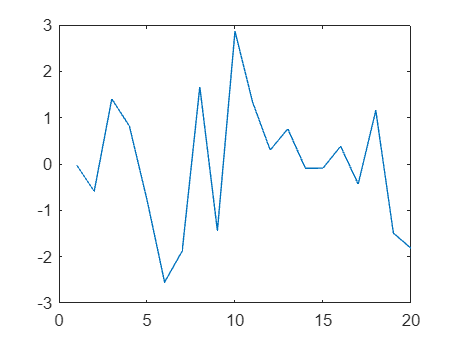

addpath('./tensorlab');
addpath('./cvx');

% Define system dimensions
statenum = 3;
outputnum = 1;
inputnum = 1;
maxTime = 20; % Total time for simulation of historical data
predTime = 1; % Part of the time that is the future

% Create a discrete-time random state space model
sys = drss(statenum, outputnum, inputnum);

% Generate a persistently exciting input for historical data
% For example, a random signal
u_trajectory = randn(inputnum, maxTime);

% New input for prediction
newInputTime = predTime; % Length of new input
uf = randn(inputnum, newInputTime); % New input sequence
%uf = zeros(inputnum,1); %zero input

% Simulate the system to generate historical outputs
% Assuming zero initial state for simplicity
x0 = zeros(statenum, 1); % Initial state
[data, t, x] = lsim(sys, u_trajectory', linspace(0, maxTime-1, maxTime), x0);

plot(data)


data = data/1

data =   -0.019516936571910
  -0.590031578472483
   1.404318512021295
   0.818031720629998
  -0.774801866872710
  -2.550565171628894
  -1.878523195361235
   1.666100297996926
  -1.439581337576363
   2.865155425250130


dataLength = length(data);

lag = 5;

% Create the full Hankel matrix without missing values initially
HankelMatrix = mosaicHankel(u_trajectory, data, lag) 

HankelMatrix =   -0.016638703029203  -0.504754621955871   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354
  -0.504754621955871   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354  -0.316795788353721
   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354  -0.316795788353721   0.945730848399757
   0.827966273483170  


rank(HankelMatrix)

ans =      8



% Define the number of points we want to predict (missing at the end)
numPredict = 1;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns

% For the last column
mask(end-numPredict+1:end, end) = false;

%{
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end
%}

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Display the mask and modified Hankel matrix to check
disp(mask);

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



disp(HankelMatrix);

  -0.016638703029203  -0.504754621955871   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354
  -0.504754621955871   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354  -0.316795788353721
   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354  -0.316795788353721   0.945730848399757
   0.827966273483170  -0.608802919289


% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin quiet %sdp for logs
    variable CompleteHankel(size(HankelMatrix))
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end
% Check the completion status
disp(cvx_status);

Solved


% Extract the predicted values from the completed Hankel matrix
CompleteHankel

CompleteHankel =   -0.016638702597790  -0.504754621037638   1.144894033946956   0.827966272991799  -0.608802917908509  -2.234960910045649  -1.814283626283889   1.279986951703145  -1.088095160750025   2.275154349382957   1.409012137949619   0.315441227324282   0.692770945531308  -0.017046650422512  -0.067053952448653   0.326195786860008
  -0.504754622825125   1.144894031021630   0.827966271662142  -0.608802917566354  -2.234960910350003  -1.814283625309465   1.279986953256543  -1.088095161732728   2.275154349798404   1.409012138436269   0.315441228341958   0.692770946883417  -0.017046648178923  -0.067053951073116   0.326195790748472  -0.316795782010132
   1.144894028079942   0.827966263033136  -0.608802929149566  -2.234960900752703  -1.814283631206385   1.279986951242746  -1.088095148546791   2.275154346467021   1.409012140851362   0.315441224700987   0.692770957734237  -0.017046658755527  -0.067053936339447   0.326195786129851  -0.316795779559541   0.945730882655971
   0.827966273623823

HankelMatrix

HankelMatrix =   -0.016638703029203  -0.504754621955871   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354
  -0.504754621955871   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354  -0.316795788353721
   1.144894032941735   0.827966273483170  -0.608802919289292  -2.234960909560528  -1.814283625165828   1.279986950987142  -1.088095161363381   2.275154349080466   1.409012138772497   0.315441226517833   0.692770948355414  -0.017046650221009  -0.067053950337087   0.326195789577354  -0.316795788353721   0.945730848399757
   0.827966273483170  


predictedValues = CompleteHankel(end, end-numPredict+1:end);
disp('Predicted value:');

Predicted value:


format long;
disp(predictedValues);

  -1.819138411658137



disp('Actual value:');

Actual value:


disp(transpose(data(end-numPredict+1:end)))

  -1.819138359819858



%rmse(predictedValues,transpose(data(end-numPredict+1:end)))
currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)

currentError =      2.849606116530703e-08


Now we're going to check how well our program runs over some iterations.

iter = 10;
errors = zeros(iter,1);

cvx_begin quiet

for i=1:iter
    % Define system dimensions
    statenum = 3;
    outputnum = 1;
    inputnum = 1;
    maxTime = 100; % Total time for simulation of historical data
    predTime = 1; % Part of the time that is the future
    
    % Create a discrete-time random state space model
    sys = drss(statenum, outputnum, inputnum);
    
    % Generate a persistently exciting input for historical data
    % For example, a random signal
    u_trajectory = randn(inputnum, maxTime);
    
    % New input for prediction
    newInputTime = predTime; % Length of new input
    uf = randn(inputnum, newInputTime); % New input sequence
    %uf = zeros(inputnum,1); %zero input
    
    % Simulate the system to generate historical outputs
    % Assuming zero initial state for simplicity
    x0 = zeros(statenum, 1); % Initial state
    [data, t, x] = lsim(sys, u_trajectory', linspace(0, maxTime-1, maxTime), x0);
    
    data = data/1
    dataLength = length(data);
    
    lag = 5;
    
    % Create the full Hankel matrix without missing values initially
    HankelMatrix = mosaicHankel(u_trajectory, data, lag);
    
    % Define the number of points we want to predict (missing at the end)
    numPredict = 1;
    
    % Create a logical mask for the Hankel matrix with all ones (no missing data)
    mask = true(size(HankelMatrix));
    
    % Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
    % These points appea5r in the last 'numPredict' rows of the last columns
    mask(end-numPredict+1:end, end) = false;
    %{
    for i = 1:numPredict
        mask(end-i+1, end-numPredict+i:end) = false;
    end
    %}
    
    % Now, apply the mask to set the last 'numPredict' points as NaN (missing)
    HankelMatrix(~mask) = NaN;
    
    % Proceed with matrix completion using the nuclear norm minimization (using CVX)
    cvx_begin quiet %sdp for logs
        variable CompleteHankel(size(HankelMatrix))
        minimize(norm_nuc(CompleteHankel))
        subject to
            % Ensure the known entries remain the same
            CompleteHankel(mask) == HankelMatrix(mask);
    cvx_end
    
    predictedValues = CompleteHankel(end, end-numPredict+1:end);
    currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues);
    errors(i,1) = currentError;
end

data =                    0
  -0.002777954717082
  -0.023441295710064
  -0.015530025109214
   0.005985501949631
   0.006726063777065
   0.160788193839964
   0.128240909370848
  -0.026294220140937
  -0.111416419994473


data =                    0
   0.695004953049878
   1.545618795126012
   1.779476934322502
   3.919908680864648
   3.911861060159963
   1.975356489610072
   3.194706904234165
   2.726059738524765
   2.855459036387056


data =    0.223057936223479
  -0.554525501065657
   0.480058316504865
  -1.112602962914979
   1.471047823739665
  -1.893392433353839
   2.159943775008099
  -0.986723167781191
   0.476206764498553
  -1.402374229653989


data =   -1.288188457634865
   1.130781126537539
   1.614589439182774
   2.831528115992539
   1.678665954949979
   0.591025873750717
   1.476129402285678
  -2.503556742010853
  -1.123744457685323
   0.414710400380316


data =   -0.741600360127850
  -0.558219161162724
   0.754089881884700
   1.517859133629308
   0.312240700149519
  -0.562792521478639
  -1.359741287993213
  -0.804652095905076
   0.650113990232078
  -0.026468165080426


data =   -0.636582306048054
  -1.621962627153676
  -0.418252315810369
  -0.594231320390225
   1.978910811075501
   0.157965902561040
  -0.398181021604675
  -0.544859895888470
   0.373551027784484
  -0.432697218365338


data =    0.414873509958663
   0.195663414685459
  -0.099918162677351
   0.420072723399130
   0.447506128728406
   0.579379472178906
   0.626165776980993
   0.837407781336071
   1.613912507530594
   3.059187884613664


data =                    0
   0.451165342970186
   0.061175583034234
  -4.086886710084344
  -2.145235385556325
  -0.914957242390014
   2.294082878373751
  -1.580816978181804
   1.209827599610138
   0.972048708901667


data =                    0
  -0.297168371215964
   0.984970766887740
  -3.111557614561659
   6.246827978088149
  -7.966341352938657
   7.465130683576795
  -5.846929321964726
   2.049976666984590
  -1.281310803329579


data =   -1.134595911904343
  -1.193013405257044
   4.068255401918221
   1.026793399317418
   0.553288823569633
   1.301241959254793
  -1.389333572638738
   2.709972444992036
  -3.807581563915915
   0.467172339522905



avgError = sum(errors,1)/iter;

disp("Average error: "+avgError)

Average error: 6.4135e-08


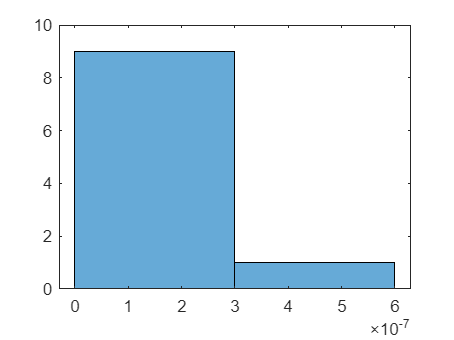

histogram(errors);

We observe that the error is incredibly small, even without any scaling applied. 